# Getting Started with betterFigs

## Description

This script wraps the popular [export_fig](https://www.mathworks.com/matlabcentral/fileexchange/23629-export_fig) and [linspecer](https://au.mathworks.com/matlabcentral/fileexchange/42673-beautiful-and-distinguishable-line-colors-colormap?s_tid=ta_fx_results) packages and adds functionality to make better looking plots in MATLAB.

## System Requirements

[export_fig](https://www.mathworks.com/matlabcentral/fileexchange/23629-export_fig) requires the installation of [ghostscript](http://ghostscript.com) for vector formatting and [Xpdf](http://xpdfreader.com) for eps formatting.

## Features

betterFigs allows you to easily set figure properties to consistently produce high quality figures. Figures can then be easily saved into vector formats to avoid any pixelation.

## Examples

Always include betterFigs without any input arguments at the top of your script:

betterFigs;

To create a simple plot with the default settings, simply call betterFigs after creating the plot:

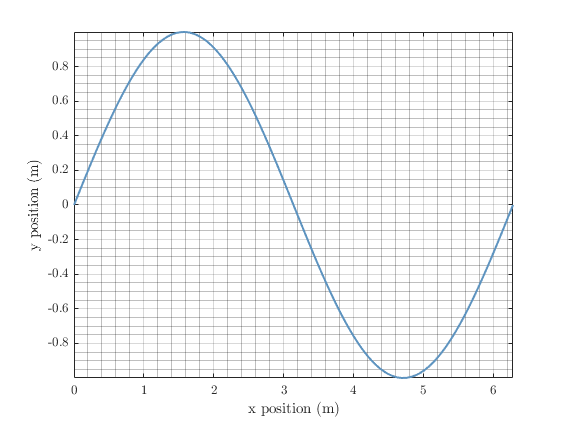

figure('Name', 'Sin(x)');
x = linspace(0,2*pi);
y = sin(x);
plot(x, y);
xlabel("x position (m)");
ylabel("y position (m)");
betterFigs;

Easily scale figure widths in terms of a given page width. By default the page width is an A4 page with margins. To create a figure with a width approxiamtely equal to 1/2 an A4 page excluding margins:

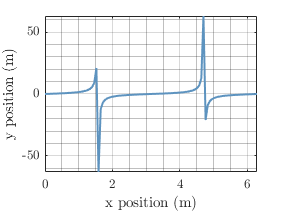

figure('Name', 'Tan(x)');
x = linspace(0,2*pi);
y = tan(x);
plot(x, y);
xlabel("x position (m)");
ylabel("y position (m)");
betterFigs('saveWidth', 0.5);

Save figures easily into your directory. Note that a new directory will be created in the parent folder if it doesn't already exist. 

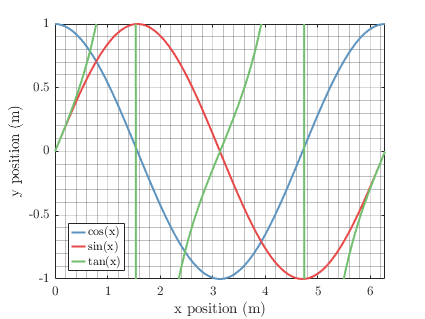

figure('Name', 'TrigonometryFunctions');
hold on;
x = linspace(0,2*pi);
plot(x, cos(x), 'DisplayName', 'cos(x)');
plot(x, sin(x), 'DisplayName', 'sin(x)');
plot(x, tan(x), 'DisplayName', 'tan(x)');
ylim([-1, 1]);
xlim([0, 2*pi]);
xlabel("x position (m)");
ylabel("y position (m)");
legend;
betterFigs('saveFig', true, 'saveWidth', 0.75, 'shrinkLeg', true);

Note the legend size is also reduced here for a more compact figure.